mesh =   FEMesh with properties:

             Nodes: [2×1246 double]
          Elements: [6×582 double]
    MaxElementSize: 0.1789
    MinElementSize: 0.0894
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'

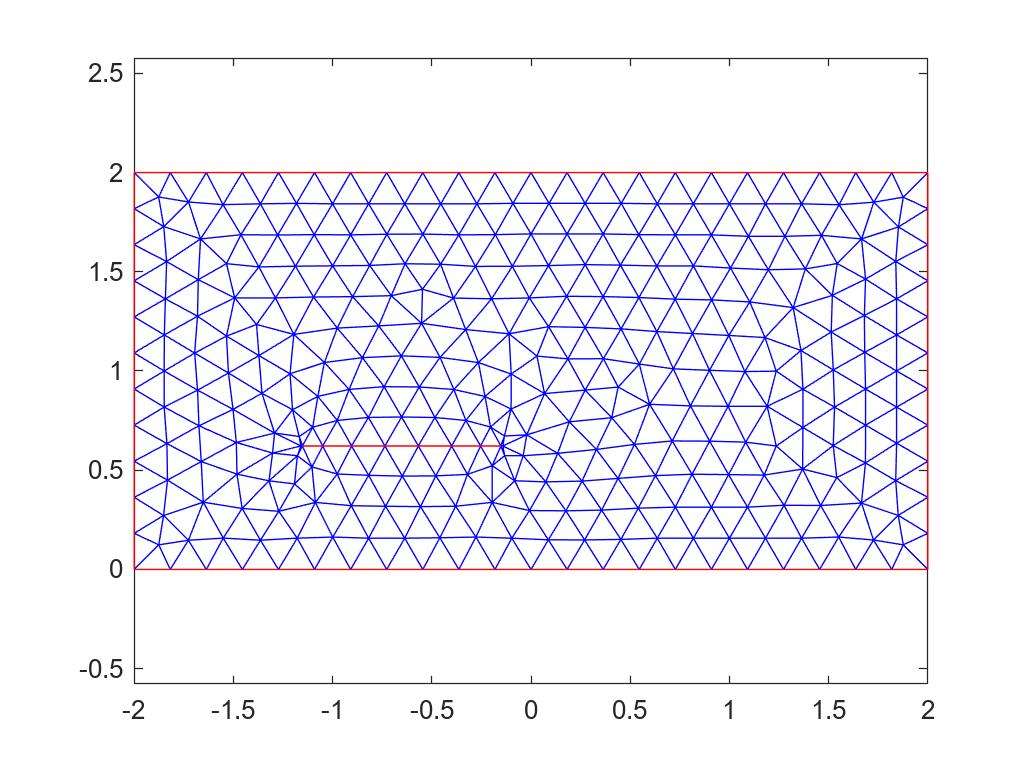

A =      1     2     6     7


ans =   ThermalMaterialAssignment with properties:

             RegionType: 'face'
               RegionID: 1
    ThermalConductivity: 25
            MassDensity: 8000
           SpecificHeat: 500

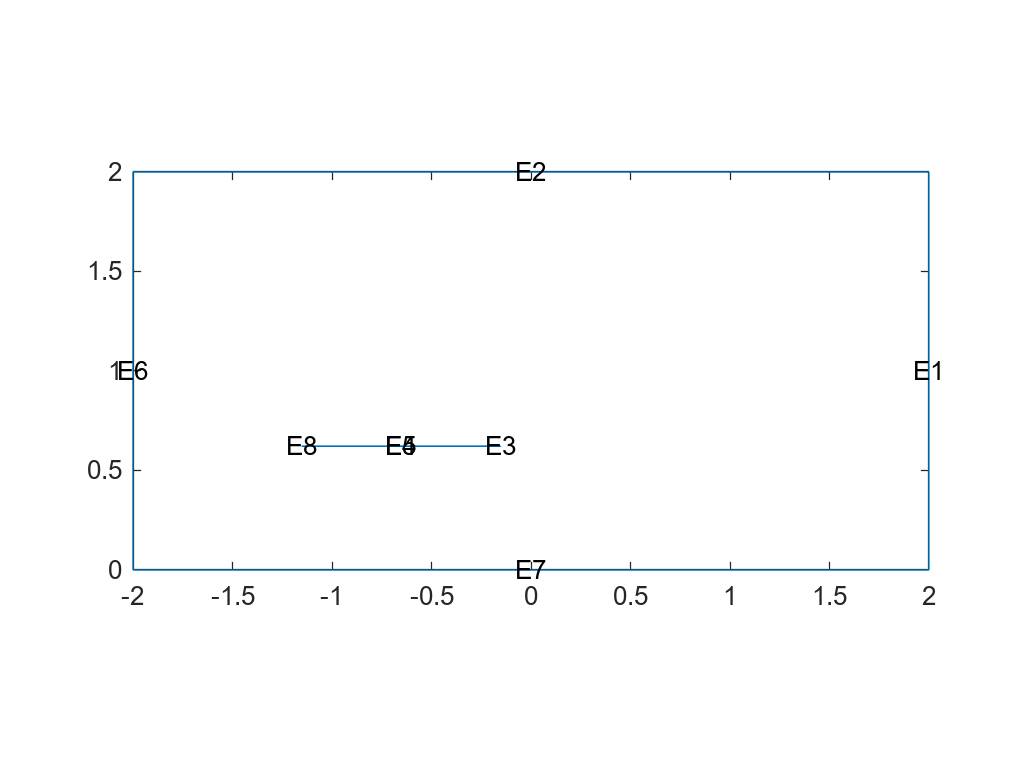

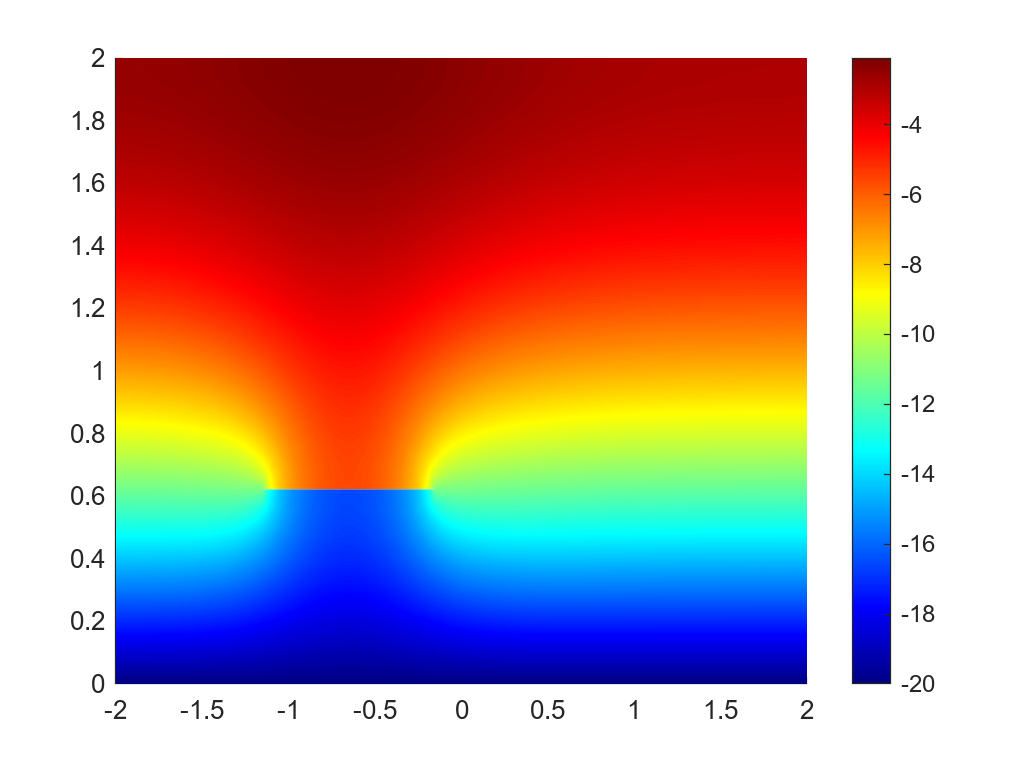

temperatureProfile =   TransientThermalResults with properties:

      Temperature: [1246×1001 double]
    SolutionTimes: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800 1900 2000 2100 2200 2300 2400 2500 2600 2700 2800 2900 3000 3100 3200 3300 3400 3500 3600 3700 3800 3900 4000 4100 4200 4300 4400 4500 4600 4700 … ]
       XGradients: [1246×1001 double]
       YGradients: [1246×1001 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]

Simulation 1 completed


clear
% Define parameters
numSimulations = 1;

%Positive dataset 
%imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Sim_Group_2\SG2_Images_Temp';

%Postive+ dataset 
%imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Sim_Group_2\SG2_PositivesPlus';

%Postive++ dataset 
%imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Sim_Group_2\SG2_PositivesPlusPlus';



%Negative dataset
imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Sim_Group_2\dumbpointer';



% Loop through simulations
for simIdx = 1:numSimulations
    % Run thermal simulation using the PDE Toolbox
    temperatureProfile = runThermalSimulation(simIdx)
    
    % Save temperature profile image
    saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx);
    
    disp(['Simulation ', num2str(simIdx), ' completed']);
end

function temperatureProfile = runThermalSimulation(simIdx)
    % Create PDE model
    thermalmodel = createpde("thermal", "transient");




    % Positive data creation (Plate contains a crack) 


    CrackWidth = 0.001; 
    CrackLength = 1; 
    CrackLocationX = -1.5 + rand(); 
    CrackLocationY = 0.5 + rand(); 
    cx = CrackLocationX; 
    cy = CrackLocationY; 
    cw = CrackWidth; 
    cl = CrackLength; 
    
    % Store the crack coordinates in a data structure
    crackCoordinates = struct('x', cx, 'y', cy, 'width', cw, 'length', cl);
    
    % Convert the data structure to JSON and save it to a file
    jsonStr = jsonencode(crackCoordinates);
    jsonFileName = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Sim_Group_2\dumbpointer\crack_coordinates.json'; 
    fid = fopen(jsonFileName, 'w');
    fwrite(fid, jsonStr);
    fclose(fid);


    rect1 = [3 4 -2 2 2 -2 0 0 2 2]' ;
    rect2 = [3 4 cx cx+cl cx+cl cx cy cy cy+cw cy+cw]';
    gd =[rect1 rect2];
    ns = char('rect','ellip');
    ns = ns';
    sf = 'rect-ellip';
    [dl,bt] = decsg(gd,sf,ns);
    geometryFromEdges(thermalmodel,dl);
    mesh  = generateMesh(thermalmodel)
    pdeplot(mesh)
    ylim([-1,1])
    axis equal
    A = [1,2,6,7]
    thermalBC(thermalmodel,"Edge",A(randi(length(A),1)),"Temperature",randi([-100 100]));
    thermalBC(thermalmodel,"Edge",A(randi(length(A),1)),"Temperature",randi([-100 100]));
    %thermalBC(thermalmodel,"Edge",7,"HeatFlux",-5);
    %thermalBC(thermalmodel,"Edge",7,"HeatFlux",-50); 
    thermalProperties(thermalmodel,"ThermalConductivity",25,...
                           "MassDensity",8000,...
                           "SpecificHeat",500)
    thermalIC(thermalmodel,0);  
 


    %Negative data (no crack inside the plate) 
%{ 
    rect1 = [3 4 -2 2 2 -2 0 0 2 2]' ;
    gd =[rect1];
    ns = char('rect');
    ns = ns';
    sf = 'rect';
    [dl,bt] = decsg(gd,sf,ns);
    geometryFromEdges(thermalmodel,dl);
    mesh = generateMesh(thermalmodel)
    pdeplot(mesh)
    ylim([-1,1])
    axis equal
    thermalBC(thermalmodel,"Edge",randi([1 4]),"Temperature", randi([-100 100]));
    thermalBC(thermalmodel,"Edge",randi([1 4]),"Temperature", randi([-100 100]));
    %thermalBC(thermalmodel,"Edge",2,"Temperature",-simIdx * 10);
    %thermalBC(thermalmodel,"Edge",7,"HeatFlux",-5);
    %thermalBC(thermalmodel,"Edge",7,"HeatFlux",-50); 
    thermalProperties(thermalmodel,"ThermalConductivity",25,...
                           "MassDensity",8000,...
                           "SpecificHeat",500)
    thermalIC(thermalmodel,0);
%}

    



    

    tlist = 0:100:100000;
    temperatureProfile = solve(thermalmodel,tlist);
    figure(2*simIdx)
    pdegplot(thermalmodel,"EdgeLabels","on")
    figure(2*simIdx + 1)
    pdeplot(thermalmodel,"XYData",temperatureProfile.Temperature(:,end), ...
                "ColorMap","jet")
end

% Image saving function for temperature profile
function saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx)
    % Create a new figure
    figure;
    
    % Create a pdeplot for the 2D temperature data
    pdeplot(temperatureProfile.Mesh.Nodes, [], temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature(:,end),'ColorMap', 'jet');
    
    % Add title and labels
    title(['Temperature Profile (Simulation ', num2str(simIdx), ')']);
    xlabel('X');
    ylabel('Y');
    
    % Save the pdeplot as a PNG image
    tempImageName = sprintf('TemperatureProfile_%d.png', simIdx);
    tempImagePath = fullfile(imagePath, tempImageName);
    savePDEPlotAsPNG(gcf, tempImagePath);
    
    % Close the figure
    close(gcf);
end

% Function to save pdeplot as PNG
function savePDEPlotAsPNG(fig, imagePath)
    % Save the figure as PNG
    saveas(fig, imagePath, 'png');
end

% Function to extract contours
function contourImage = extractContours(temperatureProfile)
    % Create a new figure
    figure;
    
    % Create a pdecontour plot
    contourf(temperatureProfile.Mesh.Nodes, temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature);
    
    % Add title and labels
    title('Temperature Contours');
    xlabel('X');
    ylabel('Y');
    
    % Capture the contour plot
    contourImage = getframe(gcf);
    
    % Close the figure
    close(gcf);
end

% Function to save contour image
function saveContourImage(contourImage, imagePath, simIdx)
    % Save the contour image as a PNG
    contourImageName = sprintf('ContourImage_%d.png', simIdx);
    contourImagePath = fullfile(imagePath, contourImageName);
    imwrite(contourImage.cdata, contourImagePath);
end
